# Read all the images 

clear;clc; close all;
%Change enable to 1 if you want to check the progression of image
%segmentation
enable=0;
if(enable==0)
    fprintf("Intermediate images will not be printed\n");
else
    fprintf("Intermediate images will be printed\n");
end

Intermediate images will not be printed



% height and width of the image to analyse
h=256;w=256;

% Directory path 
directory = 'Datasets\Task1\Images'; % Folder where the images are stores
folderpath='Train'; % Folder where we want so save the images with masks to

% Get a list of all files in the directory
fileList = dir(fullfile(directory, '*.jpg'));

% Loop through the list and read each image
%If you want to test all the images just change the 5 for numel(fileList)
images = cell(1, numel(fileList)); % Initialize cell array to store images
list=[1 ,2 ,9 ,29 ,38 ];

for i = 1:numel(fileList)

    % Get the file name
    fileName = fullfile(directory, fileList(i).name);
    
    % Read and resize the image
    image = imresize(imread(fileName),[h w]);
    
    % Store the image in the cell array
    
    images{i} = image;

end

% Display the images like and the respectives histograms
if(enable==1)
    figure;
    figure;
    subplot(2,5,1);imshow(images{1});title('Image 1');
    subplot(2,5,2);imshow(images{2});title('Image 2');
    subplot(2,5,3);imshow(images{3});title('Image 3');
    subplot(2,5,4);imshow(images{4});title('Image 4');
    subplot(2,5,5);imshow(images{5});title('Image 5');
    subplot(2,5,6);imhist(images{1});title('Histogram 1');
    subplot(2,5,7);imhist(images{2});title('Histogram 2');
    subplot(2,5,8);imhist(images{3});title('Histogram 3');
    subplot(2,5,9);imhist(images{4});title('Histogram 4');
    subplot(2,5,10);imhist(images{5});title('Histogram 5');
end


## Pre-processing

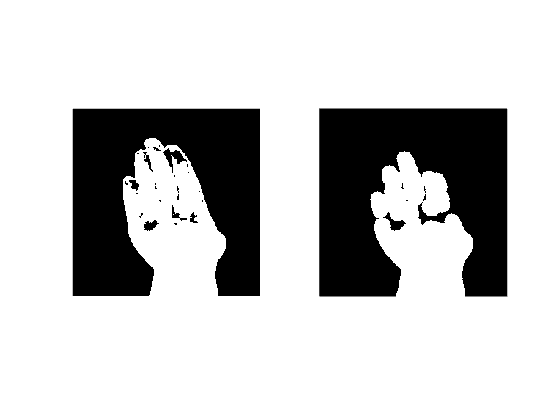

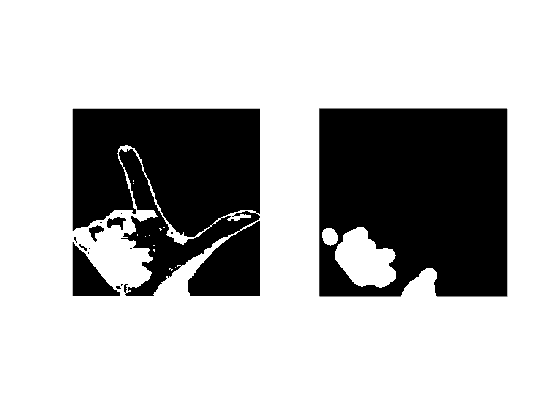

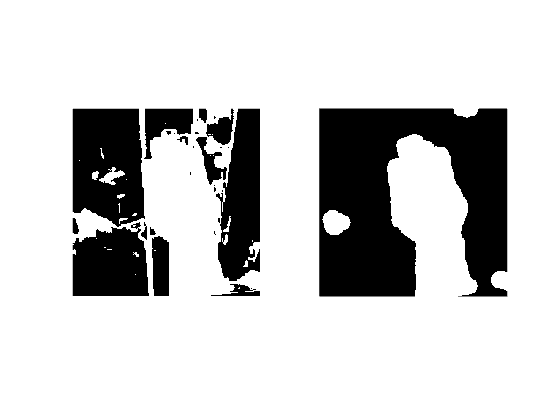

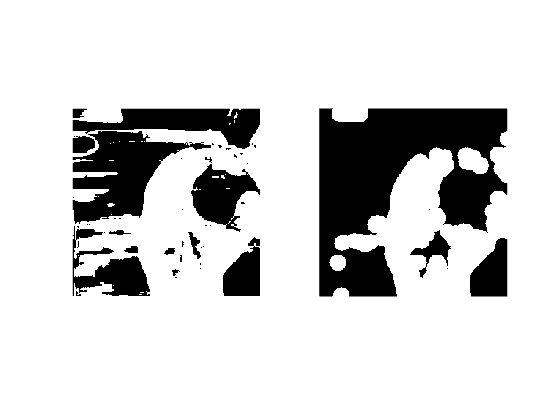

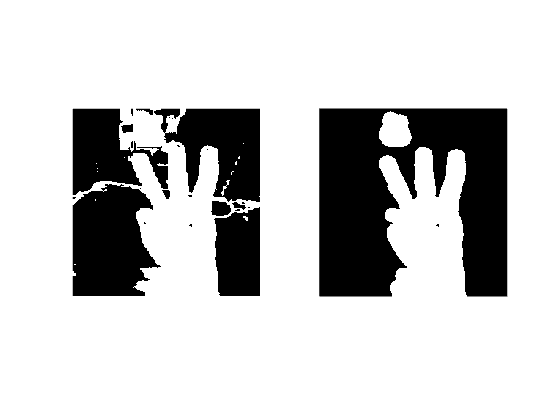

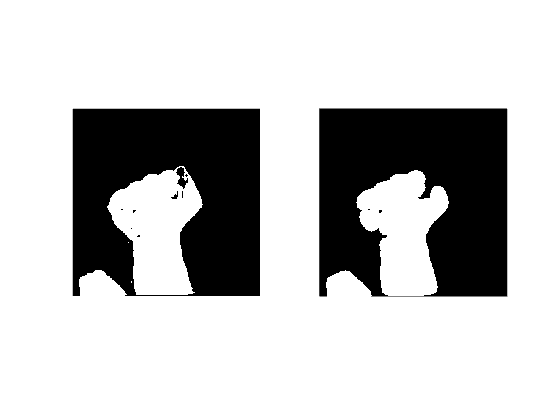

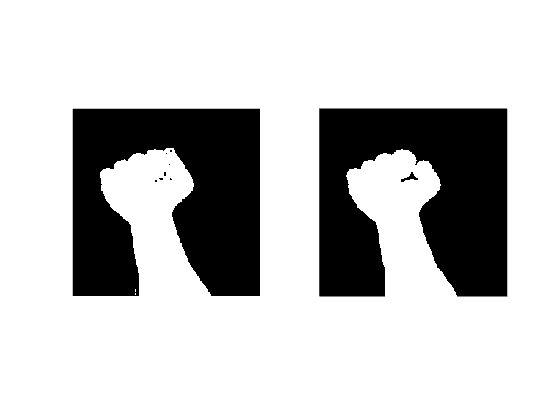

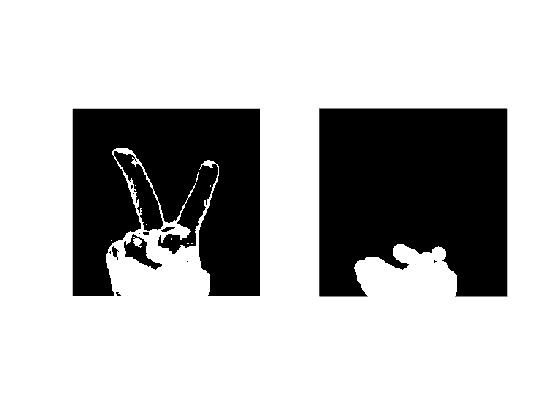

%Using just one image to test
figure;
se1=strel('sphere',10);

for j=1:numel(fileList)
    Img=images{j};

    % Img_g=rgb2gray(Img);
    % 
    % [counts,~] = imhist(Img_g);
    % To=otsuthresh(counts)*255
    % Tmax_x=max(counts);
    % for i=1:256
    %     if(counts(i)==Tmax_x)
    %         Tmax=i
    %         break;
    %     end
    % end
    % 
    %     %Find the threshold to apply a binarization, we divide by 255 to normalise the value
    %     if counts(Tmax+10) < 1000  
    %         threshold = To;
    %     elseif(Tmax<=10)
    %         threshold=round((To+Tmax)/4)
    %     else
    %         threshold=round((To+Tmax)/2)
    %     end
    % 
    %         threshold=threshold/255
    % 
    % 
    %     if(Tmax<=120)
    %         Img_fore=imbinarize(Img_g,threshold);
    %     else
    %         Img_fore=~imbinarize(Img_g,threshold);
    %   end
        
    %YCbCr
    YCbCr=rgb2ycbcr(Img);
    Cb=YCbCr(:,:,2);
    Cr=YCbCr(:,:,3); 
    %HSV
    HSV=rgb2hsv(Img);

    [r,c,~]=find(Cr >= 140 & Cr <= 160 & Cb >= 90 & Cb <= 170 & HSV(:,:,1)<0.95);
    
    % fprintfEnd1');

    Img_S_e = zeros(h, w);
    numind = size(r);

    for i=1:numind
        Img_S_e(r(i),c(i)) = 1;
    end

    Img_open=imopen(Img_S_e,se1);

    figure();
    subplot(1,2,1);imshow(Img_S_e);
    subplot(1,2,2);imshow(Img_open);
end



    %Eliminate smaller objects

    se1=strel('sphere',10);

    Img_open=imopen(Img_S_e,se1);

    figure();
    subplot(1,2,1);imshow(Img_S_e);
    subplot(1,2,2);imshow(Img_open);


    [L,n]=bwlabel(Img_S_e);
    
    s=regionprops(L)

s = 17×1 struct array with fields:
    Area
    Centroid
    BoundingBox


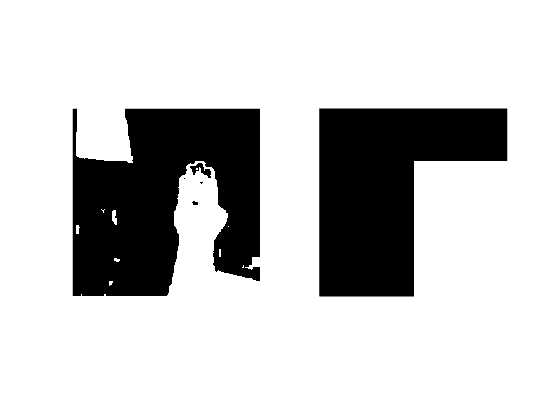

    a_max=0;
    i_max=0;
    for i=1:size(s,1)
        if(s(i).Area<1000)
            
        if(s(i).Area>a_max)
            i_max=i;
            a_max=s(i).Area;
        end
    end
    
    
    
    
    % Create BB image
    from_row = ceil(bb(2));
    to_row = from_row + bb(4) - 1;
    from_col = ceil(bb(1));
    to_col = from_col + bb(3) - 1;
    
    bb_img = zeros(h, w);
    for i = from_row:to_row
        for j = from_col:to_col
            bb_img(i, j) = 1;
        end
    end
    
    figure;
    subplot(1,2,1);imshow(Img_S_e)
    subplot(1,2,2);imshow(bb_img);